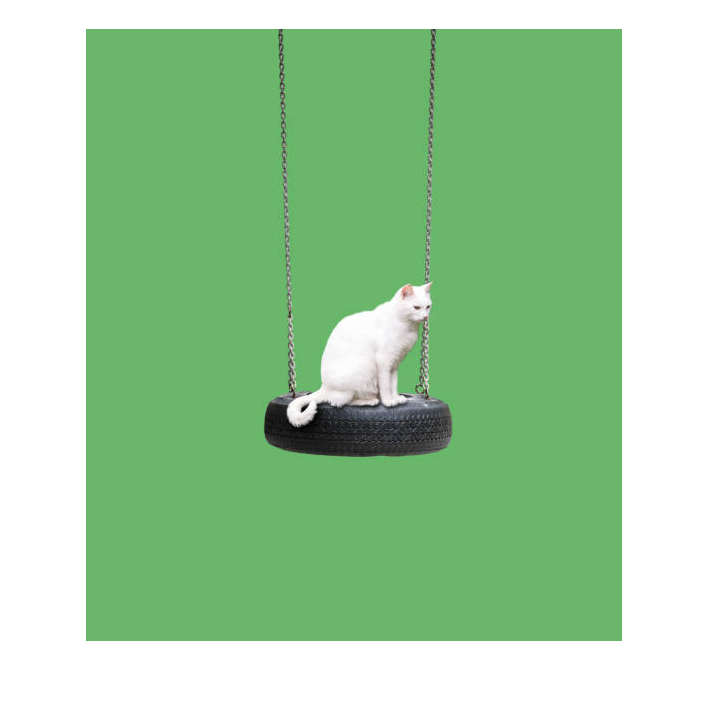

chat = imread("chat.jpg");
arbre = imread("arbre.jpg");
imshow(chat)

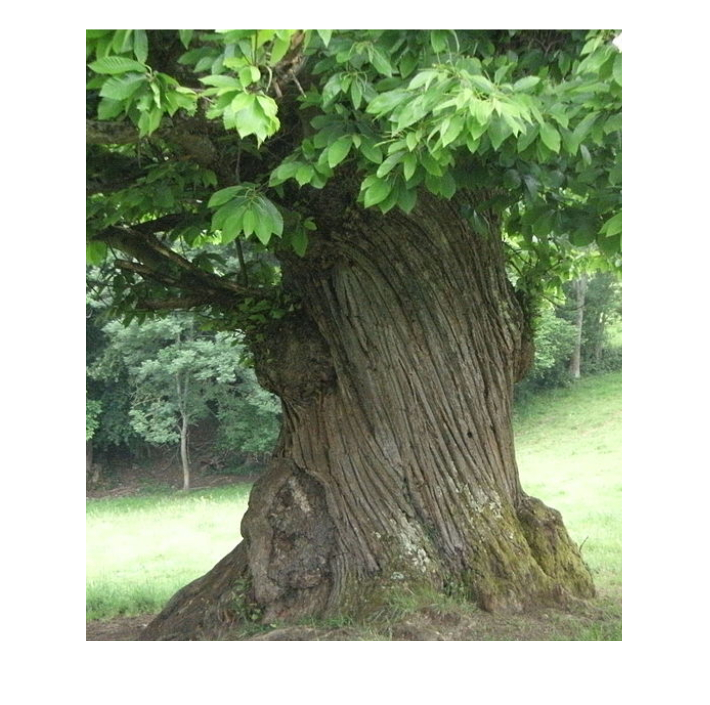

imshow(arbre)

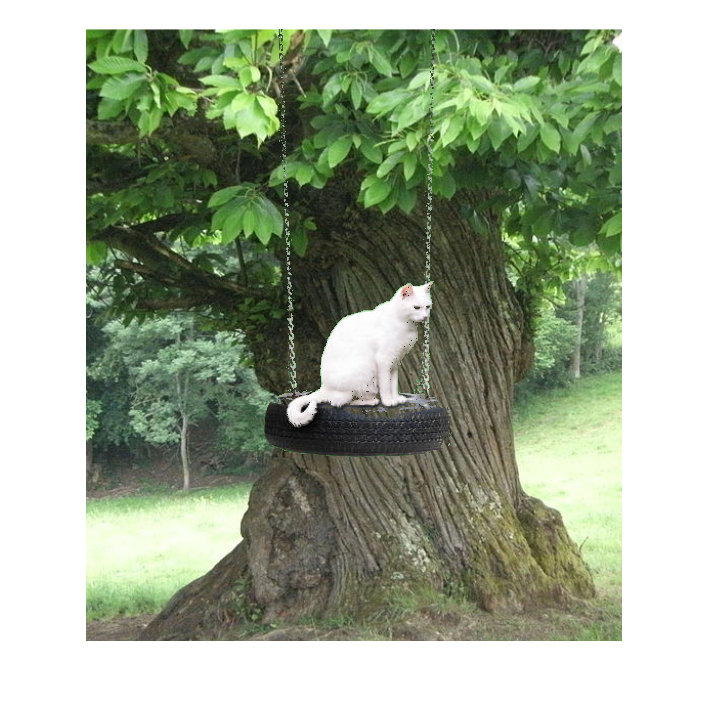

chat_r = chat(:,:,1);
chat_g = chat(:,:,2);
chat_b = chat(:,:,3);
fond_r = chat(1,1,1);
fond_g = chat(1,1,2);
fond_b = chat(1,1,3);
marge_r = 20;
marge_g = 0;
marge_b = 5;

mask = (chat_r > fond_r + marge_r | chat_r < fond_r - marge_r) ...
    & (chat_b > fond_b + marge_b | chat_b < fond_b - marge_b ) ...
    & (chat_g > fond_g + marge_g | chat_g < fond_g - marge_g);

rendu = arbre.*cast(~mask,class(arbre)) + chat.*cast(mask, class(chat));
imshow(rendu)

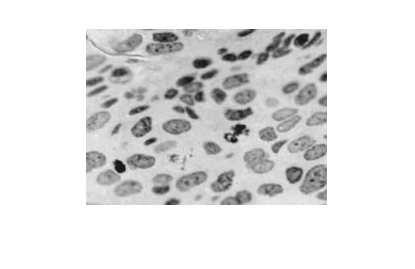

noyaux = imread("noyaux.jpeg");
imshow(noyaux)

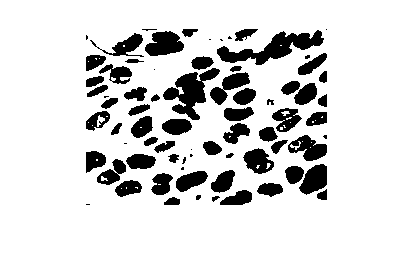

rendu = im2bw(noyaux, 0.70);
imshow(rendu)

T = graythresh(noyaux)

T = 0.6275

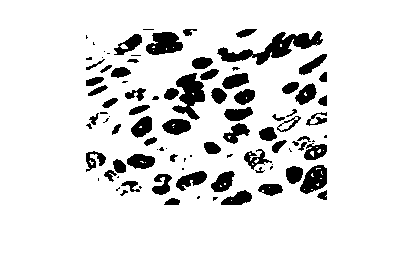

rendu = im2bw(noyaux, T);
imshow(rendu)

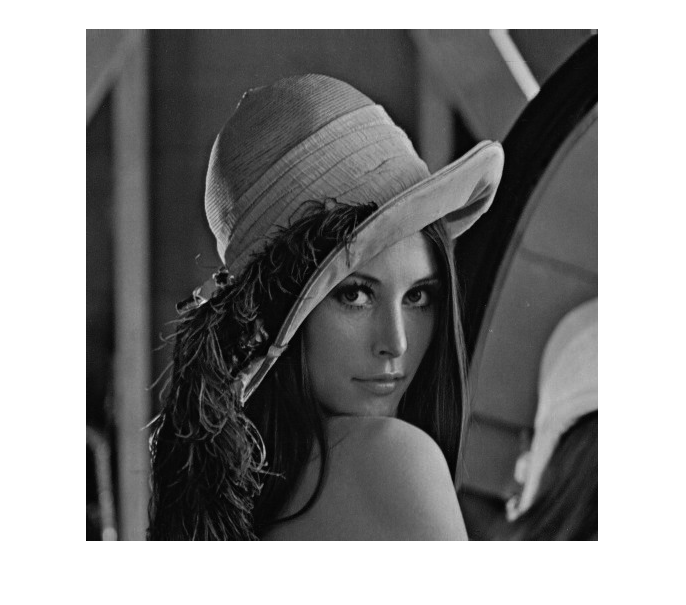

lena = imread("lena_nb.jpg");
imshow(lena)

maxi = max(max(lena))

maxi = uint8
235

mini = min(min(lena))

mini = uint8
0

C = (maxi-mini)/(maxi+mini)

C = uint8
1

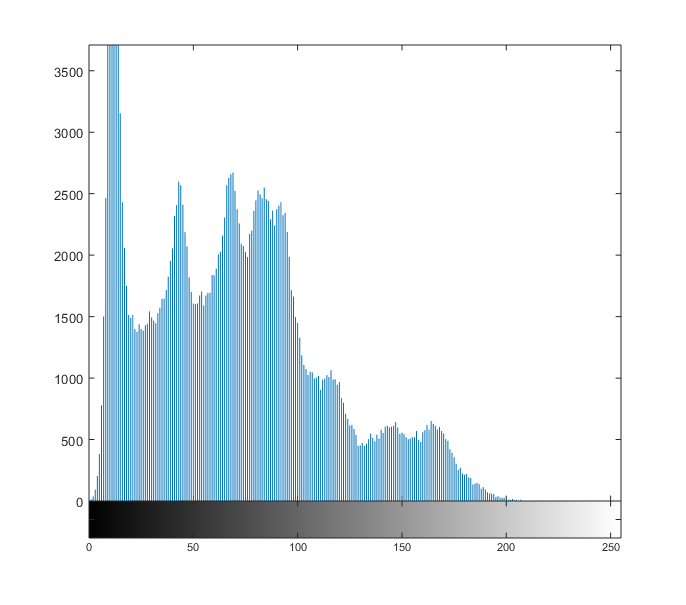

imhist(lena)

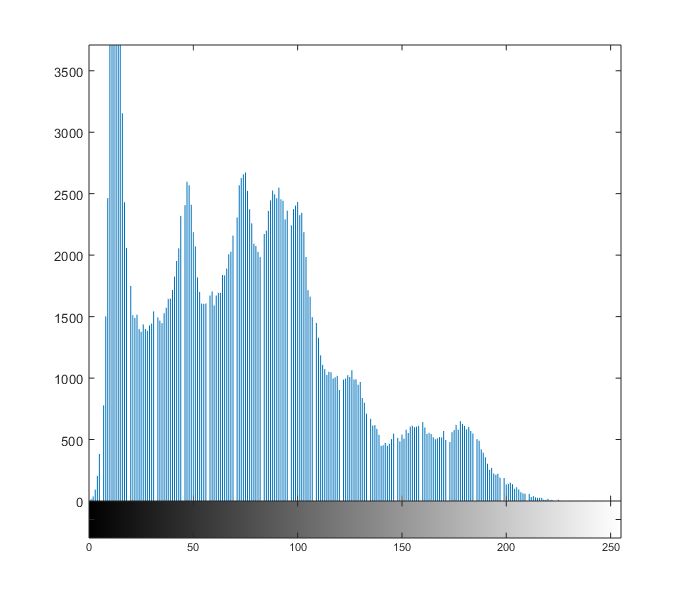

%rendu = (lena - mini)*(255/(maxi-mini));
etal = lena * (255/235);
imhist(etal)

max(max(etal))

ans = uint8
255

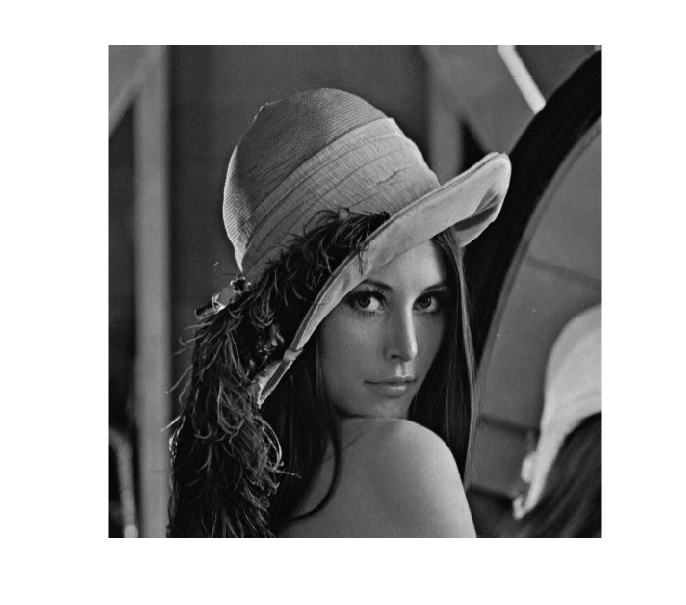

imshow(etal)

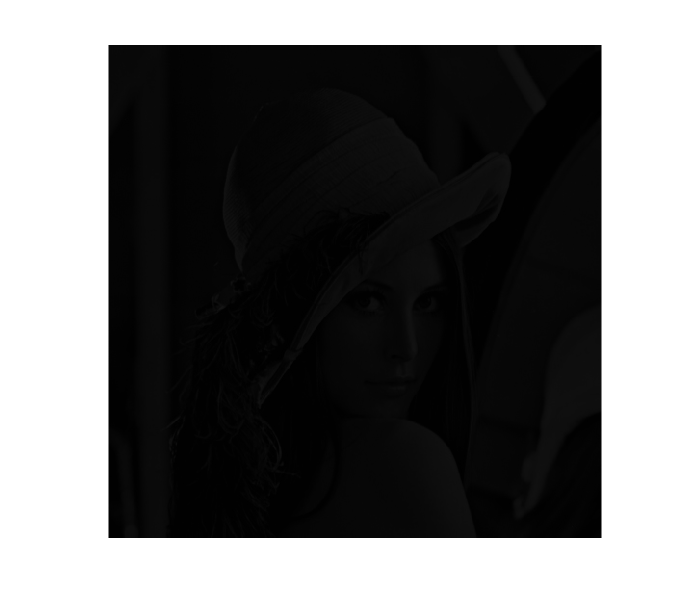

diff = etal - lena;
imshow(diff)

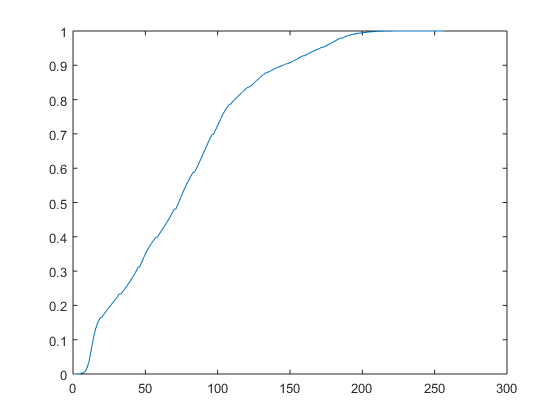

[counts, bin] = imhist(lena);
cum = cumsum(counts)/(512*512);
plot(cum)

egal = (cum(lena+1))

egal =     0.7863    0.8014    0.8057    0.7919    0.7969    0.7602    0.8014    0.7969    0.8014    0.7863    0.8014    0.7806    0.7340    0.8098    0.7806    0.7429    0.7429    0.7340    0.8014    0.7806    0.7247    0.7340    0.7340    0.7743    0.7429    0.7677    0.7518    0.7247    0.7429    0.7518    0.7429    0.7429    0.7247    0.7743    0.7429    0.7969    0.7806    0.8177    0.7969    0.8217    0.8255    0.8098    0.8255    0.8481    0.8520    0.8598    0.8598    0.8366    0.8520    0.8404
    0.7919    0.7969    0.8014    0.7863    0.7919    0.7602    0.7969    0.7969    0.8057    0.7919    0.7969    0.7806    0.7340    0.8057    0.7743    0.7247    0.7429    0.7429    0.7969    0.7806    0.7247    0.7340    0.7340    0.7677    0.7429    0.7602    0.7429    0.7247    0.7340    0.7429    0.7340    0.7429    0.7247    0.7743    0.7429    0.7969    0.7806    0.8177    0.7969    0.8177    0.8217    0.8098    0.8255    0.8442    0.8481    0.8598    0.8598    0.8366    0.8520  

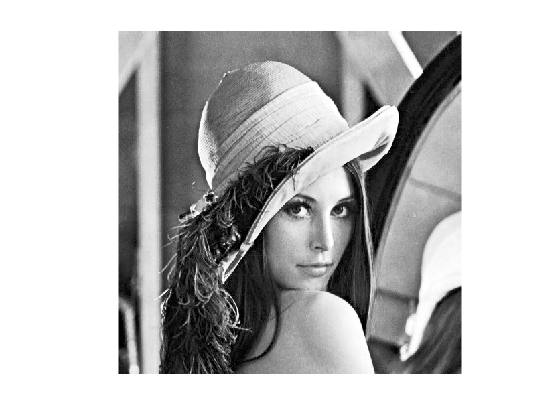

imshow(egal)

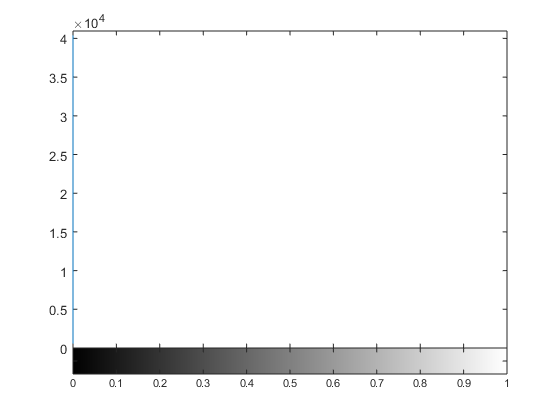

imhist(egal)

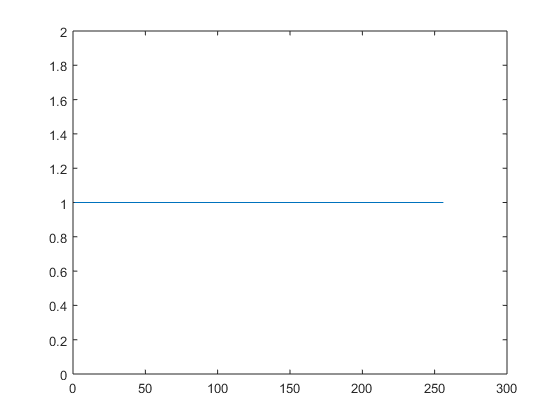

[counts, bin] = imhist(egal);
cum = cumsum(counts)/(512*512);
plot(cum)

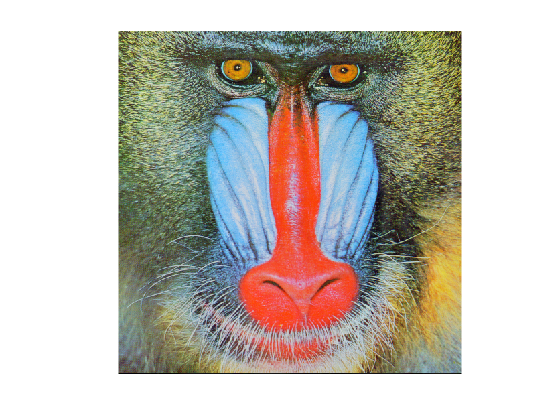

mandrill = rgb2hsv(imread("mandrill.bmp"));
imshow(hsv2rgb(mandrill))

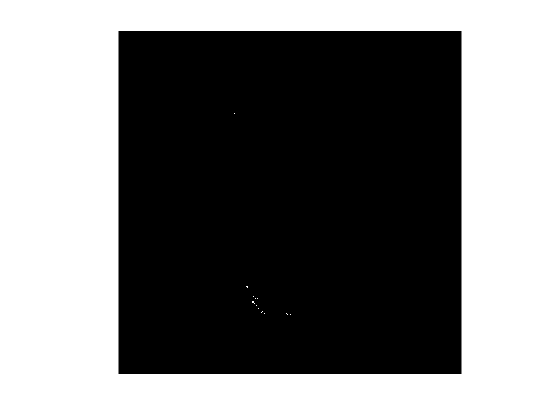

mandrill_v = floor(mandrill(:,:,3)*255);
[counts, bin] = imhist(mandrill_v);
cum = cumsum(counts)/(512*512);
egal = (cum(mandrill_v+1));
imshow(egal)